# View orientation of images

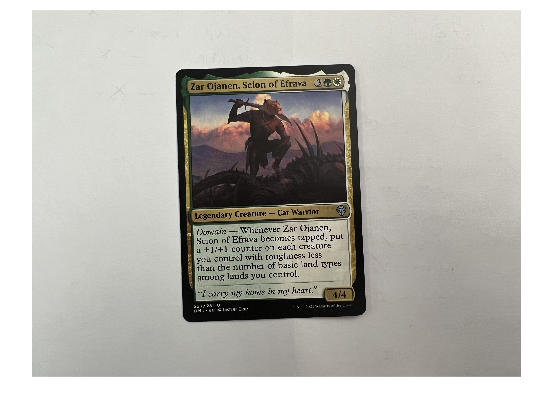

folderPath = 'C:\Users\jsozafoi\Downloads\MTG-Card-Recognition-main\MTG-Card-Recognition-main\dmuset_cards';
file_list = dir(fullfile(folderPath, '*.JPG'));

% Loop through the list of files and display each image
for i = 1:numel(file_list)
    % Read the image from file
    image_data = imread(fullfile(folderPath, file_list(i).name));
    
    % Display the image
    imshow(image_data)
    
    % Pause to allow time to view the image (optional)
    %pause(1);
end


% 88s, 66s, 59s, 71s, 68s, 104s, 86s, 63s, 61s, 60s

# standardize card image

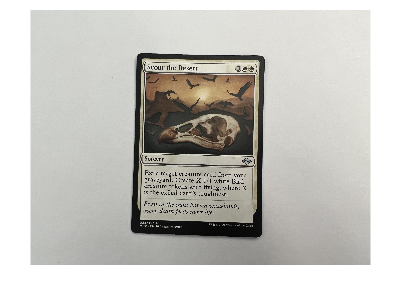

% Input image
realImg = imread("scour.JPG");
% start timer
tic;

ogImg = realImg;
figure;
imshow(realImg);

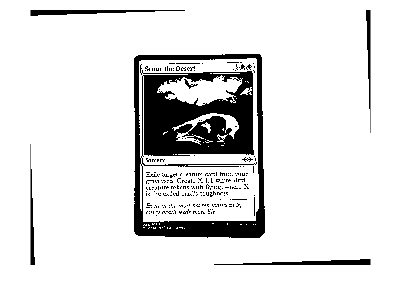


% Preprocess
realImg = rgb2gray(realImg);
realImg = medfilt2(realImg);
realImg = imbinarize(realImg,graythresh(realImg));

% Hough
[h,l,t] = hough(edge(realImg,"sobel"));
peaks = houghpeaks(h,1);
lines = houghlines(edge(realImg,"sobel"),l,t,peaks);

% Rotate
angle = atan2(lines(1).point2(2)-lines(1).point1(2),lines(1).point2(1)-lines(1).point1(1));
corrected = imrotate(realImg,rad2deg(angle)-90,'bilinear','crop');

figure;
imshow(corrected);

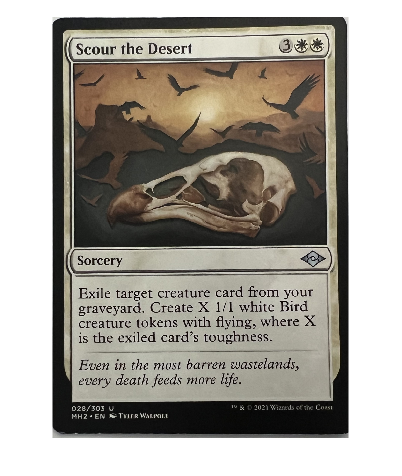


% Find Borders of Image
[r,c] = size(corrected);
northmost = r;
southmost = 1;
westmost = c;
eastmost = 1;

for i=r/2-1:r/2+1
    for j=1:c
        if corrected(i,j) == 0
            if j < westmost
                westmost = j;
            end
            if j > eastmost
                eastmost = j;
            end
        end
    end
end

for i=r/2-1:r/2+1
    for j=c:1
        if corrected(i,j) == 0
            if j < eastmost
                eastmost = j;
            end
        end
    end
end

for i=1:r
    for j=c/2-1:c/2+1
        if corrected(i,j) == 0
            if i < northmost
                northmost = i;
             
            end
        end
    end
end


for i=1:r
    for j=c/2-1:c/2+1
        if corrected(i,j) == 0
            if i > southmost
                southmost = i;
               
            end
        end
    end
end

% Crop to borders
cropRect = [westmost northmost (eastmost - westmost) (southmost - northmost)];
ogImg = imrotate(ogImg,rad2deg(angle)-90,'bilinear','crop');
croppedImg = imcrop(ogImg,cropRect);
figure;
imshow(croppedImg);

card = croppedImg;

% Test Crop
%[card, ArtCropRect] = imcrop(card);

% Full Card Resize
%normalSize = [680 488];
%card = imresize(card, normalSize);
%imshow(card);

% Card Art Crop and Resize
%ArtCropRect = [122.510000000000, 220.510000000000, 1255.98000000000, 905.980000000000];
card = imcrop(card, ArtCropRect);
artCropSize = [291 413];
card = imresize(card, artCropSize);

findCard = card;
findCard = rgb2gray(findCard);
% show time
toc

Elapsed time is 1.815029 seconds.


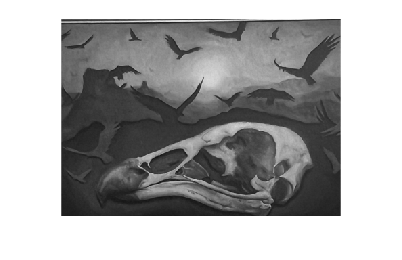

imshow(findCard)

## SURF get answer

% start time
tic;

% load in hashmaps
%load("arraySURF_dmuset.mat");
%load("arraySURF_mh2set_artcrop.mat");

% SURF feature extraction
points1 = detectSURFFeatures(findCard);
[f1,vpts1] = extractFeatures(findCard,points1);

pointsValues = [];
mostPoints = 0;
answerIndex = 1;

% Compare feature vectors
for i=1:length(arraySURFFullFinal)
    indexPairs = matchFeatures(f1, arraySURFFullFinal{1,i});
    pointsValues = [pointsValues length(indexPairs)];
    if length(indexPairs) > mostPoints
        mostPoints = length(indexPairs);
        index = i;
    end

end

% end time
toc

Elapsed time is 67.040301 seconds.


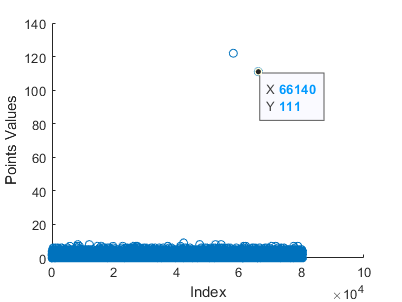


% show scatterplot
figure;
scatter(1:length(arraySURFFullFinal), pointsValues);
xlabel('Index');
ylabel('Points Values');

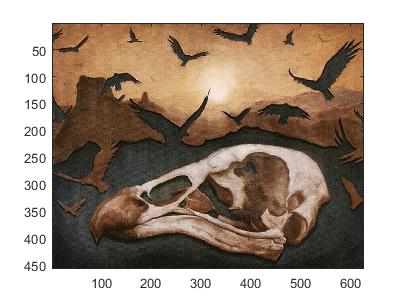


cardFinalImage = imread(arraySURFFullFinal{2,index});
figure;
imagesc(cardFinalImage);

## Get answer DCT

% Load hashmap and array
load('hash.mat');
load('hash_map.mat')
[r,c] = size(hash_array);
num_coeff = 100;
tic;

hash1 = hash_array(1,:);
theHash = zeros(2500);
lowestDist = 100000;

% Get card to compare
tempCard = card;
gray_card = rgb2gray(tempCard);

% Apply DCT
dct_img = dct2(gray_card);

% Extract the high-frequency components
num_coeffs = num_coeff;
high_coeffs = dct_img(2:num_coeffs+1, 2:num_coeffs+1);

% Generate the hash
threshold = mean(high_coeffs(:));
hash = high_coeffs > threshold;
hash1 = reshape(hash, 1, []);

distance_values=[];
% iterate through the hash_array
for i=1:r
    hash2 = hash_array(i,:);
    % Compute the Euclidean distance
    euclidean_dist = pdist([hash1; hash2], 'euclidean');
    distance_values= [distance_values euclidean_dist];
    if euclidean_dist < lowestDist
        lowestDist = euclidean_dist;
        theHash = hash2;
    end
end
toc

Elapsed time is 0.191705 seconds.


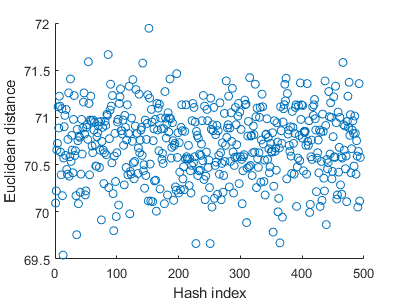

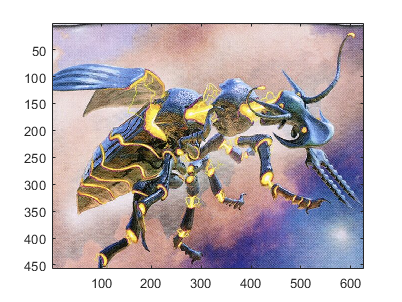


figure;
scatter(1:r, distance_values);
xlabel('Hash index');
ylabel('Euclidean distance');

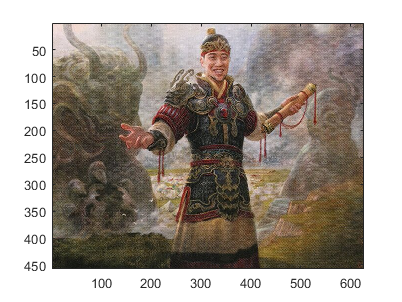


hashKey = sprintf('%d', theHash);
cardURL = hash_map(hashKey);
cardFinalImage = imread(cardURL);
imagesc(cardFinalImage);

## DCT hashing entire json

% import json
jsonStr = fileread('mh2set_artcrop.json');
jsonData = jsondecode(jsonStr);

% creating temp files for storage
%tempCard = imread(cell2mat(jsonData(1)));
%gray_card = rgb2gray(tempCard);

hash_array = zeros(length(jsonData), num_coeff*num_coeff);
hash_map = containers.Map;

for i=1:length(jsonData)
    tempCard = imread(cell2mat(jsonData(i)));
    gray_card = rgb2gray(tempCard);

    % full card crop
    %gray_card = imcrop(gray_card, cardCrop);

    % card art crop
    gray_card = imresize(gray_card, artCropSize);
    
    dct_img = dct2(gray_card);

    num_coeffs = num_coeff;
    high_coeffs = dct_img(2:num_coeffs+1, 2:num_coeffs+1);

    threshold = mean(high_coeffs(:));
    hash = high_coeffs > threshold;
    hash = reshape(hash, 1, []);

    % Store the hash in the hash array                  
    hash_array(i,:) = hash;
    cell2mat(jsonData(i));
    hash_str = sprintf('%d', hash);
    hash_map(hash_str) = cell2mat(jsonData(i));
end
save('hash_map.mat', 'hash_map');
save('hash.mat', 'hash_array');

## Run Matching Points | Testing

%dinner1 = imread("dinner.jpg");
%dinner2 = imread("https://cards.scryfall.io/art_crop/front/4/6/4613fc96-a98d-4ea8-b1e2-0a776dfd4d5a.jpg?1626101149");
dinner1 = findCard;
dinner2 = cardFinalImage;
imshow(dinner1)

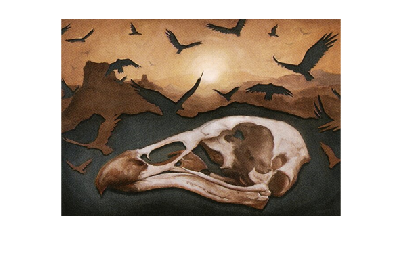

dinner2 = imresize(dinner2, artCropSize);
imshow(dinner2)
%dinner1 = rgb2gray(dinner1);
dinner2 = rgb2gray(dinner2);
points1 = detectSURFFeatures(dinner1);
points2 = detectSURFFeatures(dinner2);
[f1,vpts1] = extractFeatures(dinner1,points1);
[f2,vpts2] = extractFeatures(dinner2,points2);

indexPairs = matchFeatures(f1,f2);
matchedPoints1 = vpts1(indexPairs(:,1));
matchedPoints2 = vpts2(indexPairs(:,2));

figure; showMatchedFeatures(dinner1,dinner2,matchedPoints1,matchedPoints2);

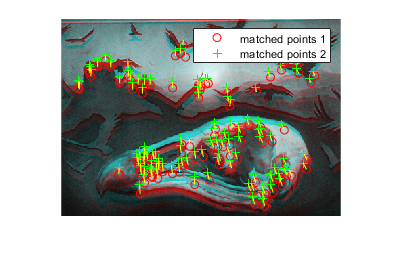

legend('matched points 1','matched points 2');

## SURF Feature Vector entire json

tic;
jsonStr = fileread('dmuset_artcrop.json');
jsonData = jsondecode(jsonStr);
jsonData = reshape(jsonData, 1, []);

hash_arraySURF = cell(1, length(jsonData));

for i=1:length(jsonData)
    tempCard = imread(cell2mat(jsonData(i)));
    gray_card = rgb2gray(tempCard);
    gray_card = imresize(gray_card, artCropSize);

    points = detectSURFFeatures(gray_card);
    [features, valid_points] = extractFeatures(gray_card,points);
    
    hash_arraySURF{i} = features;
end
arraySURF = vertcat(hash_arraySURF,jsonData);
toc

Elapsed time is 1038.361377 seconds.



%save('arraySURF_mh2set_artcrop.mat', 'arraySURF');
save('arraySURF_dmuset_artcrop.mat', 'arraySURF');

# Load in entire database json part-by-part

## initialize

jsonStr = fileread('full_artcrop.json');
jsonData = jsondecode(jsonStr);
jsonData = reshape(jsonData, 1, []);
arraySURFFinal = cell(1, length(jsonData));

load("arrays_SURF\arraySURF_1.mat");
for i=1:9999
    % store feature vector
    arraySURFFinal{i} = arraySURF{1,i};
end

load("arrays_SURF\arraySURF_all_cards_10k.mat");
for i=10000:19999
    % store feature vector
    arraySURFFinal{i} = arraySURF{1,i};
end

load("arrays_SURF\arraySURF_artcrop20k.mat");
for i=20000:29999
    % store feature vector
    arraySURFFinal{i} = arraySURF{1,i};
end

load("arrays_SURF\arraySURF_all_cards_30k.mat");
for i=30000:39999
    % store feature vector
    arraySURFFinal{i} = arraySURF{1,i};
end

load("arrays_SURF\arraySURF_artcrop40k.mat");
for i=40000:49999
    % store feature vector
    arraySURFFinal{i} = arraySURF{1,i};
end

load("arrays_SURF\arraySURF_artcrop50k.mat");
for i=50000:59999
    % store feature vector
    arraySURFFinal{i} = arraySURF{1,i};
end

load("arrays_SURF\arraySURF_all_cards_60k.mat");
for i=60000:69999
    % store feature vector
    arraySURFFinal{i} = arraySURF{1,i};
end

load("arrays_SURF\arraySURF_all_cards_70k.mat");
for i=70000:length(jsonData)
    % store feature vector
    arraySURFFinal{i} = arraySURF{1,i};
end

% concat arrays
arraySURFFullFinal = vertcat(arraySURFFinal,jsonData);